# 单摆状态方程模型

## 准备工作

将后续需要的部分变量进行定义

clc;clear;close all;    % 清屏，清除工作区变量，关闭所有图窗
tspan = [0 100];    % 设置开始和结束时间
X0 = [pi/3 ; 0];    % 设定状态变量初值，列向量
g = 9.8;l = 100;zeta = -0.05;   % 定义重力加速度g，单摆绳长l，阻尼系数ζ
IND = [0 1; -g/l zeta];   % 构造系统矩阵A

## 使用ode45函数解状态方程


$$% MathType!MTEF!2!1!+-
% feaahqart1ev3aaatCvAUfeBSjuyZL2yd9gzLbvyNv2CaerbuLwBLn
% hiov2DGi1BTfMBaeXatLxBI9gBaerbd9wDYLwzYbItLDharqqtubsr
% 4rNCHbWexLMBbXgBd9gzLbvyNv2CaeHbl7mZLdGeaGqiVu0Je9sqqr
% pepC0xbbL8F4rqqrFfpeea0xe9Lq-Jc9vqaqpepm0xbba9pwe9Q8fs
% 0-yqaqpepae9pg0FirpepeKkFr0xfr-xfr-xb9adbaqaaeGaciGaai
% aabeqaamaabaabauaakeaadaWadaqaauaabeqaceaaaeaaceWG4bGb
% aiaadaWgaaWcbaGaaGymaaqabaaakeaaceWG4bGbaiaadaWgaaWcba
% GaaGOmaaqabaaaaaGccaGLBbGaayzxaaGaaeypamaadmaabaqbaeqa
% biGaaaqaaiaaicdaaeaacaaIXaaabaGaeyOeI0YaaSaaaeaacaWGNb
% aabaGaamiBaaaaaeaacqaH+oaEaaaacaGLBbGaayzxaaWaamWaaeaa
% faqabeGabaaabaGaamiEamaaBaaaleaacaaIXaaabeaaaOqaaiaadI
% hadaWgaaWcbaGaaGOmaaqabaaaaaGccaGLBbGaayzxaaaaaa!53BC!
\[\left[ {\begin{array}{*{20}{c}}
{{{\dot x}_1}}\\
{{{\dot x}_2}}
\end{array}} \right]{\rm{ = }}\left[ {\begin{array}{*{20}{c}}
0&1\\
{ - \frac{g}{l}}&\xi 
\end{array}} \right]\left[ {\begin{array}{*{20}{c}}
{{x_1}}\\
{{x_2}}
\end{array}} \right]\]$$


ss_equation = @(t,X) IND*X;   % 构造匿名函数
[t,X] = ode45(ss_equation,tspan,X0);    % 使用ode45函数解常微分方程（状态方程形式的微分方程）

## 构造单摆模型

### version1 基本实现

如果想显示动画，可有多种选择pause(eps)|drawnow|getframe|waitfor

其中pause(eps)、drawnow、waitfor效果应当相同，显示帧数较高

getframe由于程序执行需要时间，无法在实时脚本中显示动画

### version2 优化代码

通过对网上MATLAB动画实例的查找，发现循环中不放plot函数，在循环外将初始状态全部画出，使用句柄，在循环中只需将后续每一时刻的值进行更新，不需要调用plot函数，加快运行时间，效果更好

将3部分分开画感觉效果更好，同时便于修改，不要仅使用一个plot函数画图

### version3 更改画圆方式

为了使连线只连接到圆的边界，不再使用plot自带的Marker圆格式，改为自己画圆，同样可以提前计算好数据，只在循环中更新数据

**最好不要使用动态脚本观察动画**

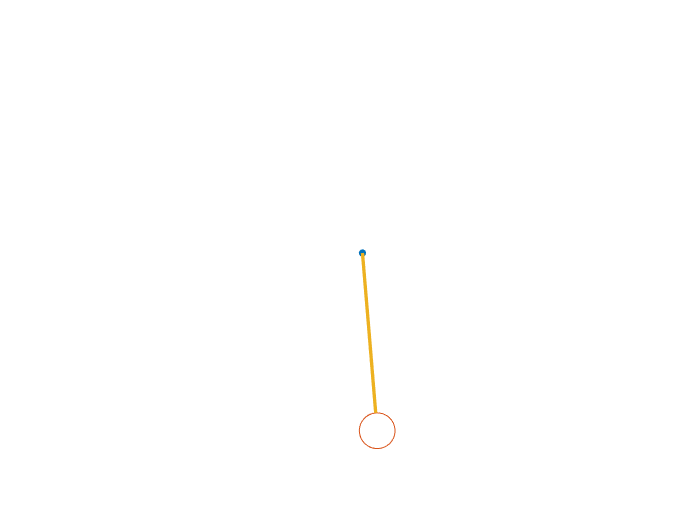

theta = X(:,1);     % 将theta取出
F(length(theta)) = struct('cdata',[],'colormap',[]);    % 预分配一个数组frame以存储影片帧
RGB{length(theta)} = 0;  % 预分配一个元胞数组im以存frame转成的image

x0 = 0; y0 = 0;     % 定义原点坐标

r = 10;             % 定义小球半径
x_center = l*cos(3/2*pi+theta);     % 计算小球圆心横坐标
y_center = l*sin(3/2*pi+theta);     % 计算小球圆心纵坐标

x_connection_points = (l-r)*cos(3/2*pi+theta);   % 计算小球连接点横坐标
y_connection_points = (l-r)*sin(3/2*pi+theta);   % 计算小球连接点纵坐标

circle = linspace(0,2*pi);          % 圆的角度0~2*pi

x_edges = r*cos(circle) + x_center;   % 计算小球边界横坐标
y_edges = r*sin(circle) + y_center;   % 计算小球边界纵坐标

xlim([-120 120])    % 规定坐标轴横坐标范围
ylim([-120 120])    % 规定坐标轴纵坐标范围
axis square         % 坐标区显示正方形
axis off            % 隐藏坐标轴

hold on     % 绘制同一张图中
p1 = plot(x0,y0,'.',"MarkerSize",15);   % 画出原点
% scatter(0,0);
p2 = plot(x_edges(1,:),y_edges(1,:));   % 画出第一个小球边界
p3 = plot([x0 x_connection_points(1)],[y0 y_connection_points(1)],"LineWidth",2);
% 画出原点与第一个连接点连线
for i = 1:length(theta)

    p2.XData = x_edges(i,:);    % 刷新小球边界横坐标数据
    p2.YData = y_edges(i,:);    % 刷新小球边界纵坐标数据
    p3.XData = [x0 x_connection_points(i)]; % 刷新连接线横坐标数据
    p3.YData = [y0 y_connection_points(i)]; % 刷新连接线纵坐标数据
%     drawnow
    F(i) = getframe;    % 获取影片帧
    RGB{i} = frame2im(F(i)); % 转为图片格式
end

## 播放视频

以50帧速率播放一遍，在实时脚本中无法实现

movie(F,1,50);  % 使用movie函数播放影片

## 将影片帧保存为动图gif

gif图的帧率就是很低

filename = 'test.gif';  % 定义文件名称
for i = 1:length(theta)
    [IND,map] = rgb2ind(RGB{i},256);
    if i == 1
        imwrite(IND,map,filename,'gif',"LoopCount",Inf,"DelayTime",0);
    else
        imwrite(IND,map,filename,'gif',"WriteMode","append","DelayTime",0);
    end
end

**效果图如下**

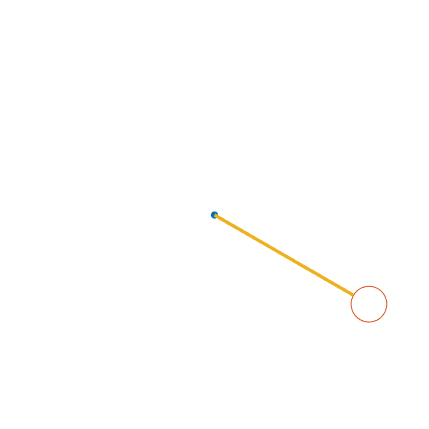

## 将影片帧保存为视频

### version1

默认是.avi格式，如果想转成.mp4格式，需要添加profile为MPEG-4，并且在编码过程中会自动将Height和Width填充为2的倍数，会显示大量警告信息

warning off % 添加warning off可忽略警告信息
% test = VideoWriter('test');
test = VideoWriter('test',"MPEG-4");
test.FrameRate = 50;    % 显示帧率
open(test)
writeVideo(test,F);
close(test)